clear all; close all;
q1=0; q2=0; q3=0; q4=0; q5=0; q6=0;
Q=[q1,q2,q3,q4,q5,q6];
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);

plot_options = {'workspace',[-10 10 -10 10 -10 10],'scale',0.05, 'view',[45 20]};
Robot_ABB = SerialLink(L,'name','ABB CRB 15000','plotopt',plot_options);
bob = SerialLink(Robot_ABB,'name','bob');
theta = linspace(0,2*pi,15);

figure(1);
hold on;
trplot(eye(4), 'width',2,'arrow');
axis([-1 1 -1 1 -0.5 1.5]);
for s=1:length(theta)
    rbot = SerialLink(Robot_ABB,'name',('bob'+string(s)));
    rbot.plot([0 theta(s) pi/2 0 0 0],'view',[45 20]);
end

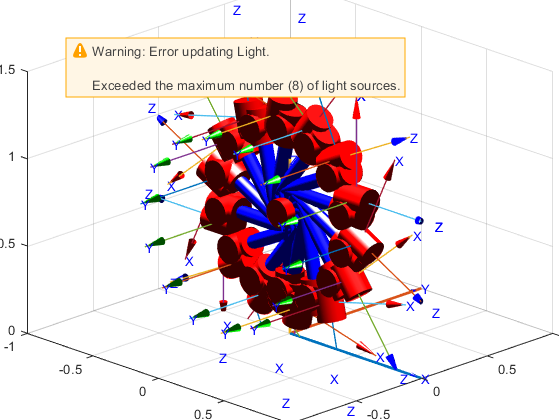


clear all; close all;
q1=0; q2=0; q3=0; q4=0; q5=0; q6=0;
Q=[q1,q2,q3,q4,q5,q6];
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);

plot_options = {'workspace',[-10 10 -10 10 -10 10],'scale',0.05, 'view',[45 20]};
Robot_ABB = SerialLink(L,'name','ABB CRB 15000','plotopt',plot_options);
bob = SerialLink(Robot_ABB,'name','bob');
theta = linspace(0,2*pi,15);

figure;
hold on;
trplot(eye(4), 'width',2,'arrow');
axis([-1 1 -1 1 0 1.5]);
for s=1:length(theta)
    rbot2 = SerialLink(Robot_ABB,'name',('bob'+string(s)));
    rbot2.plot([0 0 theta(s) 0 0 0],'view',[45 20]);
end



% ROBOTS = [Robot_ABB,bob];
% robo = SerialLink(Robot_ABB,'name',('bobo'));
% figure(2);
% hold on;
% trplot(eye(4), 'width',2,'arrow');
% axis([-1 1 -1 1 0 1.5]);
% %Robot_ABB.teach([0 0 0 0 0 0]); hold on;
% ROBOTS(1).plot([0 0 0 0 0 0])
% ROBOTS(2).plot([0 0 pi 0 0 0])
% robo.plot([0 0 pi/2 0 0 0])
% %Robot_ABB.teach([0 pi/2 -pi/2 0 -pi/2 0]);




Diseño de robot en RST

% body1 = rigidBody('body1'); 
% %creacion de la junta
% jnt1 = rigidBodyJoint('jnt1','revolute'); 
% jnt1.HomePosition = pi/4; %posición inicial
% tform = trvec2tform([0.25, 0.25, 0]); %Se crea una transformación homogenea a partir de unvector de traslacion
% % % User defined 
% setFixedTransform(jnt1,tform); %se asigna la transformacion a la junta y queda con tamaño y orientación
% body1.Joint = jnt1; %se coloca la junta en el cuerpo
% 
% 
% %creacion del robot
% robot = rigidBodyTree; %se crea la base del robot a la cual se añaden juntas
% addBody(robot,body1,'base'); %se añade el cuerpo a la base
% 
% 
% body2 = rigidBody('body2'); 
% jnt2 = rigidBodyJoint('jnt2','revolute'); 
% jnt2.HomePosition = pi/6;
% % User defined 
% tform2 = trvec2tform([1, 0, 0]); 
% % User defined 
% setFixedTransform(jnt2,tform2); 
% body2.Joint = jnt2; 
% addBody(robot,body2,'body1'); % Add body2 to body1
% 
% 
% body3 = rigidBody('body3'); 
% body4 = rigidBody('body4'); 
% jnt3 = rigidBodyJoint('jnt3','revolute'); 
% jnt4 = rigidBodyJoint('jnt4','revolute'); 
% tform3 = trvec2tform([0.6, -0.1, 0])*eul2tform([-pi/2, 0, 0]); 
% % User defined 
% tform4 = trvec2tform([1, 0, 0]); 
% % User defined 
% setFixedTransform(jnt3,tform3); 
% setFixedTransform(jnt4,tform4); 
% jnt3.HomePosition = pi/4; 
% % User defined 
% body3.Joint = jnt3;
% body4.Joint = jnt4;
% addBody(robot,body3,'body2'); % Add body3 to body2 
% addBody(robot,body4,'body2'); % Add body4 to body2
% 
% 
% 
% config = randomConfiguration(robot);% se crea una conf. aleatoria
% tform = getTransform(robot,config,'endeffector','base'); %se obtiene la MTH de robot a partir de config
